## **Topics:**

**Baxter**

- Distance between arms in certain joint states

- Distance between bases and/or arms in certain joint states

- Straightforward Inverse kinematics using robotics toolbox

**Puma 560**

- Distance from end effector to surface in environment

- Distance from end effector to surface in environment givennew information about base location

- Point in the end effector’scoordinate frame

- Straightforward Jacobiananalysis

- Straightforward Inverse kinematics using robotics toolbox

Self collisions for a Hyper Redundant 2D arm

D&H Transforms and forward kinematics in Matlab

Puma560 Setup

mdl_puma560

workspace = [-3 3 -3 3 -0.05 3];
scale = 0.7;

ang = deg2rad(0);
q = [ang ang ang ang ang ang]*pi/180;

**Inverse kinematics**

Tr = transl(1,1,1);

joint_ang = p560.ikine(Tr)

joint_ang = 	1.0e+05 *

    0.0122    1.1998   -0.0030   -0.7072    0.2893    0.2617


**Jacobian analysis**

jacAng = [0 0 10 0 20 30];
jcob = p560.jacob0(deg2rad(jacAng));
eVal = jcob(:,6)

eVal =          0
         0
         0
   -0.5000
   -0.0000
    0.8660


**Ef to floor **

q =    [pi/10,0,0,0,0,0];
p560.base = transl(0,0,0.8);

tool_to_wld = p560.fkine(q)

tool_to_wld =     0.9511   -0.3090         0    0.4763
    0.3090    0.9511         0   -0.0030
         0         0    1.0000    1.2318
         0         0         0    1.0000


distance_floor = tool_to_wld(3,4)

distance_floor = 1.2318

**Ball in tool frame**

point = transl(0.5,0,0.6) * trotx(pi/2);

Point in tool frame (p/w* inv(e/w))

q = deg2rad( [0, 45, 45, 0, 45, 0]  );
p560.base = transl(0,0,0.5);

pointInTool = inv(p560.fkine(q))* point; 

Convert to degress

eual = round(tr2eul(pointInTool,'deg'))

eual =    -90    90   -45



eual_RPY = round(tr2rpy(pointInTool,'deg'))

eual_RPY =     90     0  -135



xyz = pointInTool(1:3,4)

xyz =    -0.6025
    0.1500
   -0.2834


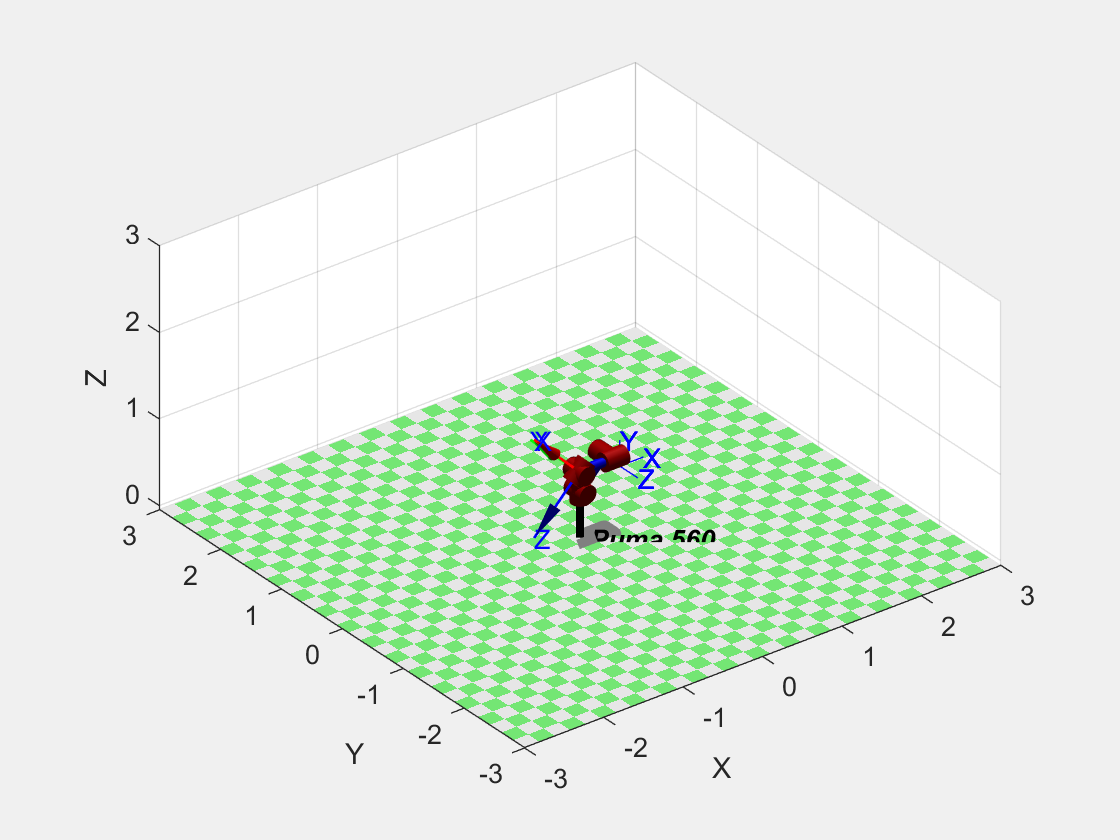


p560.plot(q,'workspace',workspace ,'scale',scale)
hold on;

trplot(point,'length',0.3);

Baxter Setup

mdl_baxter

workspace = [-0.2 1 -1.7 1.7 -0.05 1];
scale = 1;

l_q =   [3*pi/10,0,0,0,0,0,2*pi/10];
% l_q = [deg2rad(0) 0 0 0 0 0 0 ]
l_tool = left.fkine(l_q)

l_tool =    -0.5805   -0.7991   -0.1564   -0.1054
   -0.0919   -0.1266    0.9877    1.3322
   -0.8090    0.5878    0.0000    0.3100
         0         0         0    1.0000



r_q =    [4*pi/10,0,0,-2*pi/5,0,0,0];
r_tool = right.fkine(r_q);

**Distance betweeen arms in gobal frame**


%distance between left base and right end effector 
lb = left.base;
rb = right.base; 

dl = l_tool;
dr = r_tool;

distance = sqrt((lb(1,4)-r_tool(1,4))^2 +(lb(2,4)-r_tool(2,4))^2+(lb(3,4)-r_tool(3,4))^2)

distance = 1.0256


distance_between_tools = sqrt((dl(1,4)-dr(1,4))^2 +(dl(2,4)-dr(2,4))^2+(dl(3,4)-dr(3,4))^2)

distance_between_tools = 1.6236

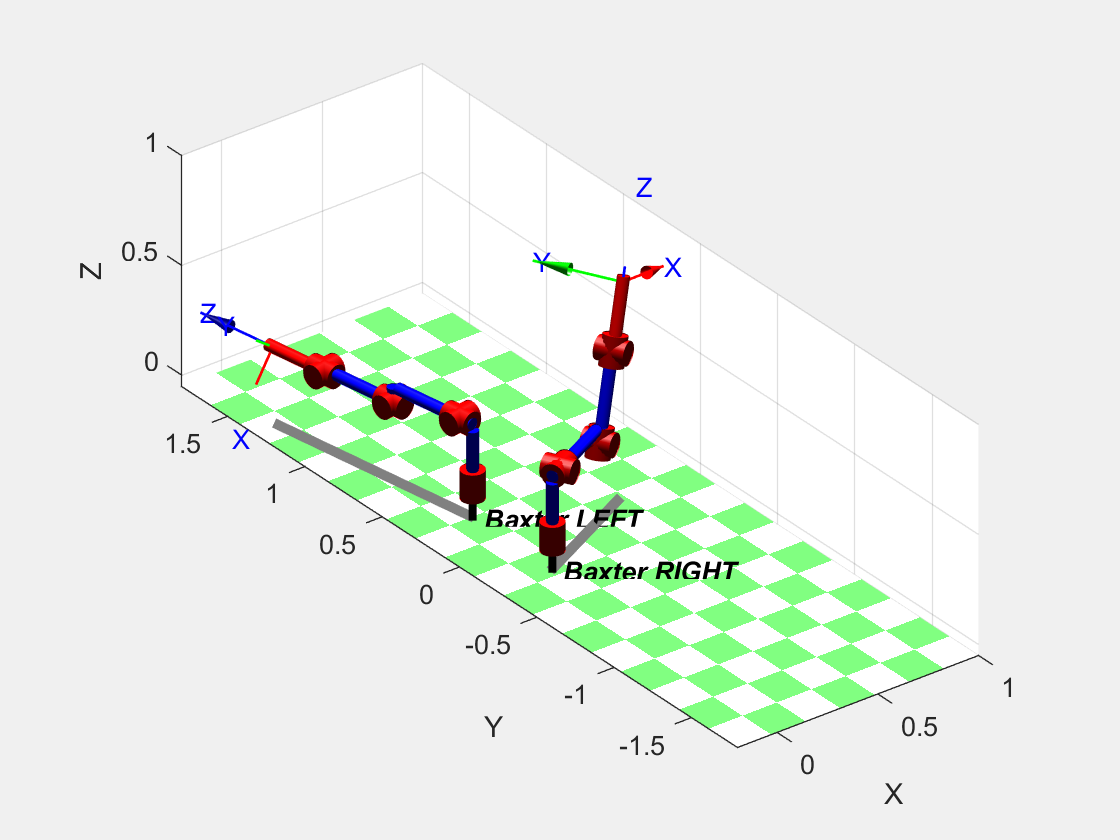




% x_distance = abs(distance_l(1,4)) + abs(distance_r(1,4))
% y_distance = abs(distance_l(2,4)) + abs(distance_r(2,4))
% z_distance = abs(distance_l(3,4)) + abs(distance_r(3,4))

left.plot(l_q,'workspace',workspace ,'scale',scale);
hold on;
right.plot(r_q,'workspace',workspace ,'scale',scale);

Hyper2d

mdl_hyper2d
workspace = [-1 1 -1 1 -0.05 1];
scale = 0.1;

q = [pi, pi/2, -pi/2, -pi/2, -pi/2, pi/2, -pi/2, pi/2, -pi/3, -pi/3]

q =     3.1416    1.5708   -1.5708   -1.5708   -1.5708    1.5708   -1.5708    1.5708   -1.0472   -1.0472


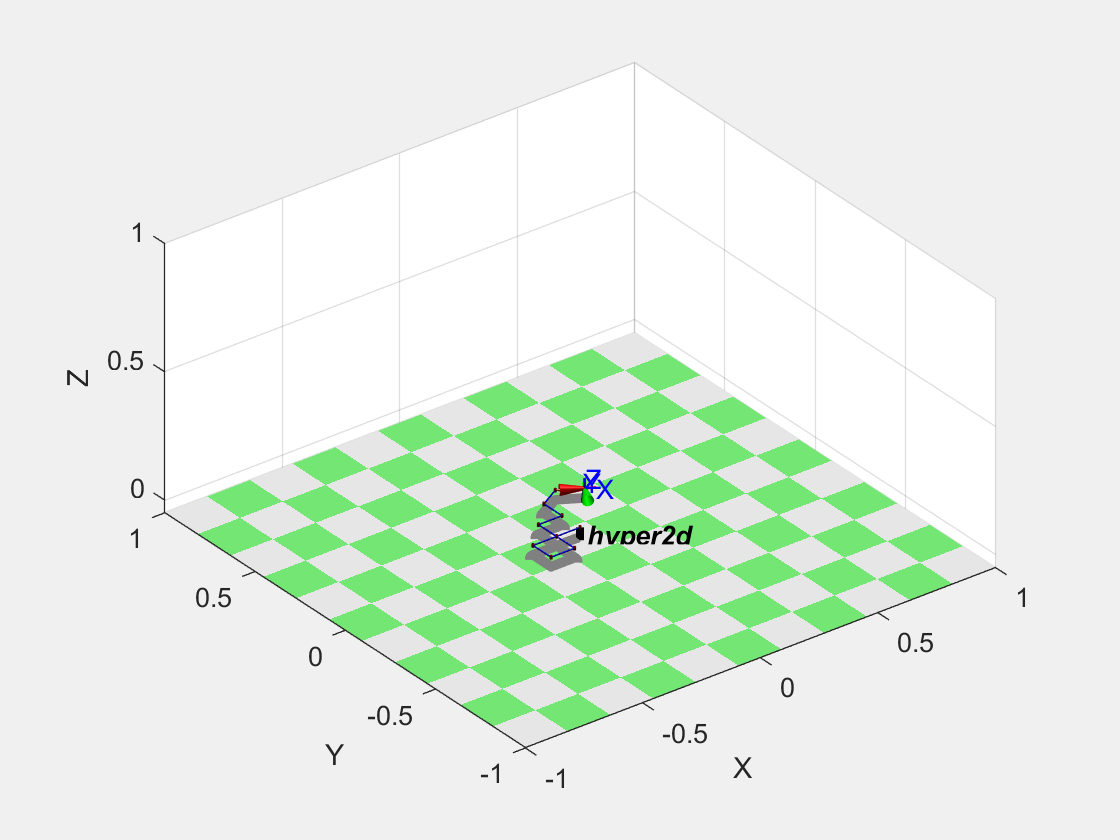


h2d.plot(q,'workspace',workspace ,'scale',scale)

D&H